# Análisis de datos

## Accendiendo a los datos

importandoDatos
anio=year(Date);

## Graficando datos

Grafico iluminado con los datos de la radiacion solar

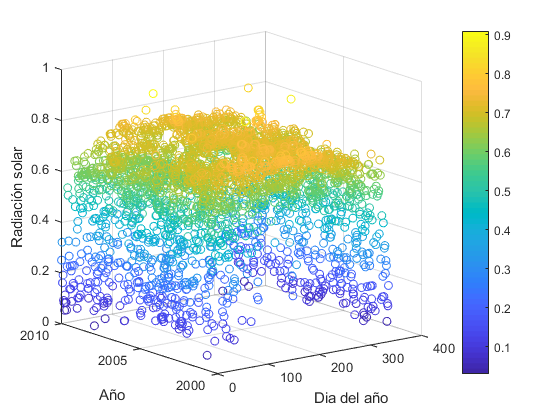

graficar(DayofYear,anio,SolRatio,[],SolRatio)

Grafico iluminado con los datos de la humedad relativa del lugar

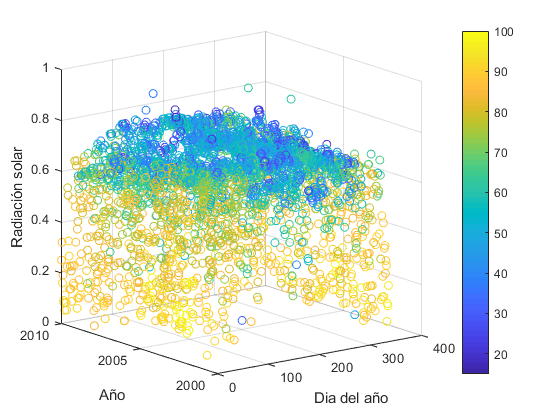

graficar(DayofYear,anio,SolRatio,[],AvgRelHum)

## Preparando los datos

indices=anio~=2006;
delT=MaxAirTemp-MinAirTemp;
train_delT=delT(indices);
train_HR=AvgRelHum(indices);
train_Rs=SolRatio(indices);
test_delT=delT(~indices);
test_HR=AvgRelHum(~indices);
test_Rs=SolRatio(~indices);%esto es un comentario

## Creando modelo

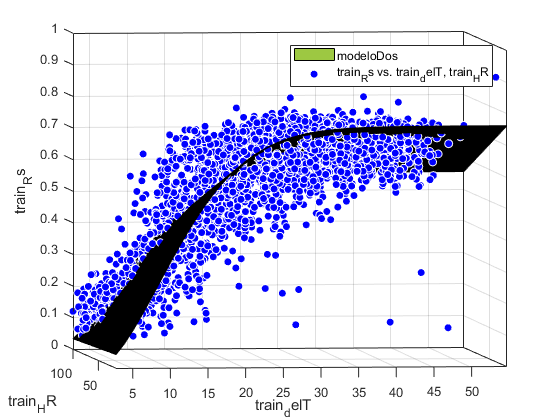

[modelo,queTanBueno]=createFit(train_delT, train_HR, train_Rs);

## Evaluacion del modelo obtenido

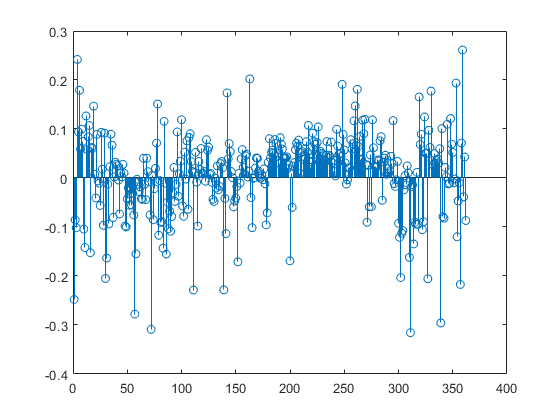

prediccion=modelo(test_delT,test_HR);
error=test_Rs-prediccion;
stem(error)